# Interactive Peak-Flow Visualization for Crag & Coffee Bouldering Hub

For this project i used crowdedness_at_the_campus_gym from kaggle. The project analyzed gym occupancy patterns at Crag & Coffee using time series data to identify peak usage periods and uncover opportunities for targetted marketting. By combinning occupancy trends with synthetic simulated social engagement data, the model highlights "prime convention Windows" time slots where physical attendance is high but online engagement is relatively low.

Occupancy trends: The heatmap was generated by constructing a 7 x 24 matrix representing average occupancy for each comination of weekday and hour. Each cell in the matrix corresponds to the mean number of people observed at a specific hour on a given day.The heatmap visualization reveals clear temporal patterns in gym usage, peak occupancy consistently occurs during late afternoon to evening hours (5pm - 8pm) on weekdays. Morning hours show significantly lower traffic, with gradual buildup through out the day. Weekend usage is more evenly distriuted, without sharp peaks. So the gym is primarly driven by after work users.

Member Persona Insight:

Early Birds (Before 12 pm): has moderate activity between 7AM - 10 AM, low congestion compared to other times.

Prime Conversion Window:

the conversion model identifies time slots where gym traffic is high and social engagement is low. These windows represent missed marketting opportunities observed pattern, several mid-week and late afternoon slots (e.g 3PM-5PM) show high conversion potential. Users are physically present but not actively engaging online.

By targatting prime conversion windows , Crag & Coffee can:

increase on site engagement, improve event participation rate, bridge the gap between physical presence and digital interaction.

The interactive dashboard successfully integrates occupancy data with behavioral insights to support strategic decision making. The ability to filter by user personas and dynamically explore peak usage patterns allows the maketting team to optimize promotional timing and maximize conversion opportunities  


clc;clear;close all;
data = readtable("C:\Users\Dell\Documents\MATLAB\crowdedness_at_the_campus_gym.csv",VariableNamingRule="preserve");
head(data, 4);

    number_people                date                 timestamp    day_of_week    is_weekend    is_holiday    temperature    is_start_of_semester    is_during_semester    month    hour
    _____________    _____________________________    _________    ___________    __________    __________    ___________    ____________________    __________________    _____    ____

         37          {'2015-08-14 17:00:11-07:00'}      61211           4             0             0            71.76                0                      0               8       17 
         45          {'2015-08-14 17:20:14-07:00'}      62414         


% The dataset has columns: hour, number_people, day_of_week(numeric), etc ....


data.Hour = data.hour;
data.Weekday = data.day_of_week

data = 62184×13 table
    number_people                date                 timestamp    day_of_week    is_weekend    is_holiday    temperature    is_start_of_semester    is_during_semester    month    hour    Hour    Weekday
    _____________    _____________________________    _________    ___________    __________    __________    ___________    ____________________    __________________    _____    ____    ____    _______

         37          {'2015-08-14 17:00:11-07:00'}      61211           4             0             0            71.76         

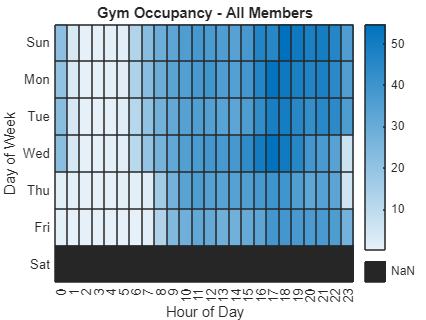


%create matrix for heatmap(7 days x 24 hours)

heatMatrix = zeros(7, 24);

for d = 1:7
    for h = 0:23
        idx = (data.Weekday == d) & (data.Hour == h);
        if any(idx)
            heatMatrix(d, h + 1) = mean(data.number_people(idx));
        else
            heatMatrix(d, h + 1) = NaN;
        end
    end
end

% labels

days = ["Sun","Mon","Tue","Wed","Thu","Fri","Sat"];
hours = string(0:23);

% Plot heatmap
figure;
heatmap(hours, days, heatMatrix);

title("Gym Occupancy - All Members");
xlabel("Hour of Day");
ylabel("Day of Week");

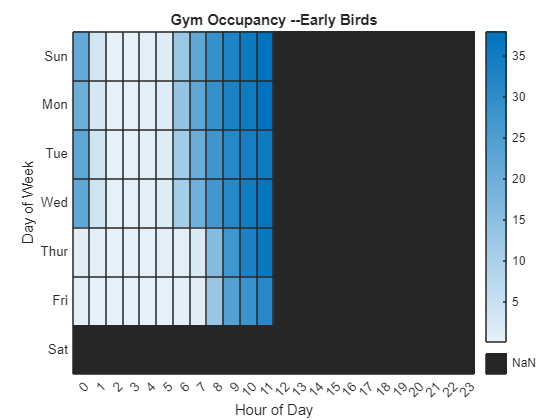


% define Member Personas
% Early Birds
early = data(data.Hour < 12, :);

%After work
afterWork = data(data.Hour >= 17, :);

% Weekend climbers
weekend = data(data.is_weekend == 1, :);

%plot Persona Heatmaps

plotPersona(early, "Early Birds");

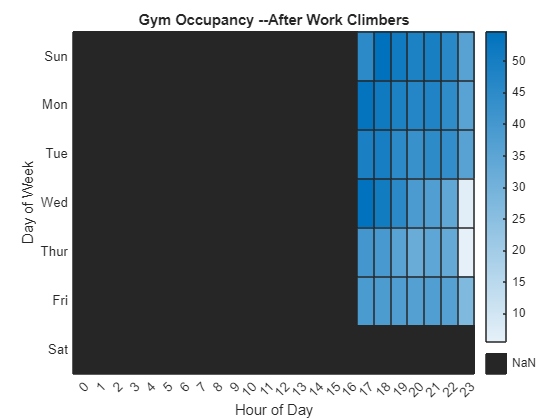

plotPersona(afterWork, "After Work Climbers");

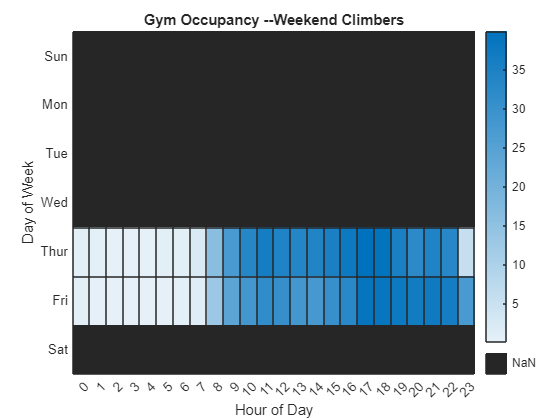

plotPersona(weekend, "Weekend Climbers");

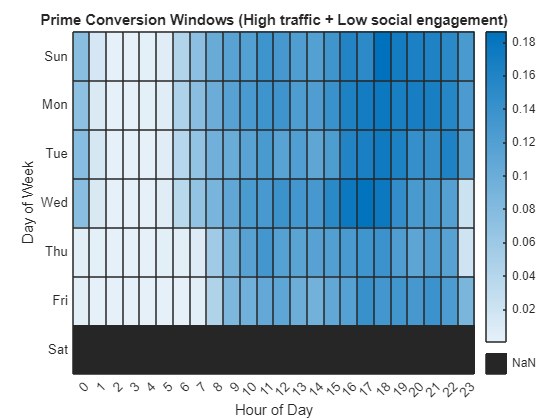


% Identify Prime conversion window
% The dataset has no social media engagement data, so we create simulated
% engagement

data.social_engagement = randi([5 100], height(data), 1);

%normalize both signals
trafficNorm = normalize(data.number_people, 'range');
socialNorm = normalize(data.social_engagement, 'range');

%conversion index = high trafic, low engagement

data.conversionScore = trafficNorm .* (1 - socialNorm);

%Let us compute average score for 7x24 matrix
primeMatrix = zeros(7,24);

for d = 1:7
    for h = 0:23
        idx = (data.Weekday == d) & (data.Hour == h);
        if any(idx)
            primeMatrix(d, h+1) = mean(data.conversionScore(idx));
        else
            primeMatrix(d, h+1) = NaN;
        end
    end
end

% plot prime conversion window Heatmap
figure;
heatmap(hours, days, primeMatrix);
title("Prime Conversion Windows (High traffic + Low social engagement)");
xlabel("Hour of Day");
ylabel("Day of Week");


% Extract recommended time slots
%top five windows where conversion opportunity is highest
[topSlots, idx] = maxk(primeMatrix(:), 5);
[dayIdx, hourIdx] = ind2sub(size(primeMatrix), idx);

disp("Recommended prime conversion windows:");

Recommended prime conversion windows:



for i = 1:5
    fprintf("%s at %02d:00 (score %.2f)\n", days(dayIdx(i)), hourIdx(i)-1, ...
        topSlots(i));
end

Sun at 18:00 (score 0.19)
Wed at 17:00 (score 0.18)
Wed at 16:00 (score 0.18)
Mon at 18:00 (score 0.18)
Wed at 18:00 (score 0.18)



% plotPersona function

function plotPersona(data, name)
 
      heatMatrix = zeros(7,24);

      for d = 1:7
          for h = 0:23
              idx = (data.day_of_week == d) & (data.hour == h);
              if any(idx)
                  heatMatrix(d, h+1) = mean(data.number_people(idx));
              else
                  heatMatrix(d, h+1) = NaN;
              end
          end
      end
      days = ["Sun","Mon","Tue","Wed","Thur","Fri","Sat"];
      hours = string(0:23);

      figure;
      heatmap(hours, days, heatMatrix);
      title("Gym Occupancy -- " + name);
      xlabel("Hour of Day");
      ylabel("Day of Week");

end
